sps = 4     % Количество выборок на символ (коэффициент избыточной выборки) /аналогично частоте дискретезации/

sps = 4

M = 16;      % Порядок модуляции
k = log2(M); % Количество битов на символ
NumBits = k*100; 
EbNo = (1:1:20);
snr = convertSNR(EbNo,'ebno', ...
    samplespersymbol=sps, ...
    bitspersymbol=k); %Перевод Eb/N0 в ОСШ
for n = 1:length(snr)
    numErr = 0;
    nBits = 0;
    while numErr < 100 && nBits < 1e4
        
        rng default  % генератор случайных чисел по умолчанию
        dataIn1 = randi([0 1],NumBits,1); % Генерация вектора двоичных данных
        % МОДУЛИРОВАНИЕ ДАННЫХ:
        dataSymbolsIn = bit2int(dataIn1,k); %Используйте функцию bit2int для преобразования 
        dataMod = qammod(dataSymbolsIn,M);  % двоичных слов k-кортежа в целочисленные символы.
                                            % 16 QAM модуляция
        % СОЗДАНИЕ ФИЛЬТРА ПРИПОДНЯТОГО КОСИНУСА:
        filtlen = 10; %Длина фильтра в символах
        rolloff = 0.25; %Коэффициент затухания фильтра
        rrcFilter = rcosdesign(rolloff,filtlen,sps); %rcosdesign функция для создания фильтра Прип.Кос.
    
        % ПРИМЕНЕНИЕ ФИЛЬТРА ПРИПОДНЯТОГО КОСИНУСА:  
        txSignal = upfirdn(dataMod,rrcFilter,sps,1); %Функция upfirdn дополняет сигнал с повышенной
                                                     %дискретизацией нулями в конце, чтобы
                                                     %очистить фильтр. Затем функция применяет фильтр
        % ПРИМЕНЕНИЕ КАНАЛ AWGN:
        
    
        rxSignal = awgn(txSignal,snr(n) ,'measured'); % Пропустить фильтрованый сигнал через AWGN канал:
    
        rxFiltSignal = ...
            upfirdn(rxSignal,rrcFilter,1,sps);       % Downsample and filter
        rxFiltSignal = ...
            rxFiltSignal(filtlen + 1:end - filtlen); % Account for delay
    
        dataSymbolsOut = qamdemod(rxFiltSignal,M);
    
        dataOut = int2bit(dataSymbolsOut,k);
    % Подсчитайте количество битовых ошибок
        numErrors = biterr(dataIn1,dataOut);
    % Увеличьте количество счетчиков ошибок и битов
        numErr = numErr + numErrors
        nBits = nBits + NumBits;
    end
    berEst(n) = numErr/nBits;
end

numErr = 40

numErr = 80

numErr = 120

numErr = 30

numErr = 60

numErr = 90

numErr = 120

numErr = 24

numErr = 48

numErr = 72

numErr = 96

numErr = 120

numErr = 17

numErr = 34

numErr = 51

numErr = 68

numErr = 85

numErr = 102

numErr = 13

numErr = 26

numErr = 39

numErr = 52

numErr = 65

numErr = 78

numErr = 91

numErr = 104

numErr = 12

numErr = 24

numErr = 36

numErr = 48

numErr = 60

numErr = 72

numErr = 84

numErr = 96

numErr = 108

numErr = 6

numErr = 12

numErr = 18

numErr = 24

numErr = 30

numErr = 36

numErr = 42

numErr = 48

numErr = 54

numErr = 60

numErr = 66

numErr = 72

numErr = 78

numErr = 84

numErr = 90

numErr = 96

numErr = 102

numErr = 1

numErr = 2

numErr = 3

numErr = 4

numErr = 5

numErr = 6

numErr = 7

numErr = 8

numErr = 9

numErr = 10

numErr = 11

numErr = 12

numErr = 13

numErr = 14

numErr = 15

numErr = 16

numErr = 17

numErr = 18

numErr = 19

numErr = 20

numErr = 21

numErr = 22

numErr = 23

numErr = 24

numErr = 25

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

numErr = 0

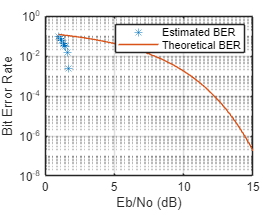

%Determine the theoretical BER curve by using the berawgn function.


berTheory = berawgn(EbNoVec,'qam',M);
semilogy(EbNoVec,berEst,'*')
hold on
semilogy(EbNoVec,berTheory)
grid
legend('Estimated BER','Theoretical BER')
xlabel('Eb/No (dB)')
ylabel('Bit Error Rate')




%прочее:


%DataIn = [dataIn1 dataIn2 dataIn3 dataIn4 dataIn5 dataIn6];
%%Каналы 6 Прд/Прм
%ChannelsFreq = [2400*10^6 2401.4*10^6;2401.4*10^6 2402.8*10^6;2402.8*10^6 2404.2*10^6;2404.2*10^6 2405.6*10^6;2405.6*10^6 2407*10^6;2407*10^6 2408.4*10^6]
%
%
%Trms = [1 2 3 4 5 6]; %Идентификаторы передатчиков
%Tranmitters = randsample(Trms,6) %Случайный порядок вещания
%
%Rxs = [1 2 3 4 5 6]; %Идентификаторы приемников
%WhereToTransmit = randsample(Rxs,6) %%Случайный порядок приема
%
%%Массив индентификаторов Прд и Прм и выделенных для них частот
%BSTarray = [Trms(1) Rxs(1) ChannelsFreq(1);Trms(2) Rxs(2) ChannelsFreq(2);Trms(3) Rxs(3) ChannelsFreq(3);Trms(4) Rxs(4) ChannelsFreq(4);Trms(5) Rxs(5) ChannelsFreq(5);Trms(6) Rxs(6) ChannelsFreq(6)];

%for n = 1:6 
%    if Tranmitters(n) == WhereToTransmit(n)
%        disp('Попытка передачи данных на свою же антенну');
%    else 
%        if Tranmitters(1) == 6  && WhereToTransmit(1) == 2 %Это хотя бы работает
%            dataOut2 = dataIn6
%        end
%        if Tranmitters(4) == 1  && WhereToTransmit(4) == 3 %Это хотя бы работает
%            dataOut4 = dataIn1
%        end
%        if Tranmitters(5) == 3  && WhereToTransmit(5) == 1 %Это хотя бы работает
%            dataOut5 = dataIn3
%        end
%        if Tranmitters(6) == 2  && WhereToTransmit(6) == 6 %Это хотя бы работает
%            dataOut6 = dataIn2
%        end
%    end
%end


%package1 = [Tranmitters(1) WhereToTransmit(2)]

%for n = 1:6 
%    if Tranmitters(n) == WhereToTransmit(m)
%        disp('Попытка передачи данных на свою же антенну');
%    else 
%        switch Tranmitters(n)
%            case 2
%                dataOut2 = dataIn1
%            case 3
%                dataOut3 = dataIn1
%            case 4
%                dataOut4 = dataIn1
%            case 5
%                dataOut5 = dataIn1
%            case 6
%                dataOut6 = dataIn1
%        end
%    end
%end

